# **Signal and System CA3**

## **Part 1.**

**1-1)** First we create our Mapset with needed characters.

characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];
Mapset = cell(2, 32);
Mapset(1, :) = num2cell(characters);
for i = 1 : length(characters)
    Mapset(2, i) = {num2str(dec2bin(i-1, 5))};
end

disp(Mapset);

  Columns 1 through 12

    {'a'    }    {'b'    }    {'c'    }    {'d'    }    {'e'    }    {'f'    }    {'g'    }    {'h'    }    {'i'    }    {'j'    }    {'k'    }    {'l'    }
    {'00000'}    {'00001'}    {'00010'}    {'00011'}    {'00100'}    {'00101'}    {'00110'}    {'00111'}    {'01000'}    {'01001'}    {'01010'}    {'01011'}

  Columns 13 through 24

    {'m'    }    {'n'    }    {'o'    }    {'p'    }    {'q'    }    {'r'    }    {'s'    }    {'t'    }    {'u'    }    {'v'    }    {'w'    }    {'x'    }
    {'01100'}    {'01101'}    {'01110'}    {'01111'}    {'10000'}    {'10001'}    {'10010'}    {'10011'}    {'10100'}    {'10101'}    {'10110'}    {'10111'}

  Columns 25 through 32

    {'y'    }    {'z'    }    {' '    }    {'.'    }    {','    }    {'!'    }    {'"'    }    {';'    }
    {'11000'}    {'11001'}    {'11010'}    {'11011'}    {'11100'}    {'11101'}    {'11110'}    {'11111'}



**1-2)** In `coding` function first we handle the errors such as not finding the character inside Mapset or the message being longer than the image. When checking for Mapset, we also translate the input message to the corresponding binary string. Then we put each bit of binary string inside the pixels LSB using `bitset` function.

path = './data/';
file = 'pic.png';
source = [path, file];
orgPicture = imread(source);
orgPicture = rgb2gray(orgPicture);
codedPicture = coding(orgPicture, 'signal;', Mapset);

**1-3) **Now we use `subplot` to show both original and coded pictures. We cannot observe the difference between them because we put the message in the Least Significant Bit of each pixel so the change is not very significant for the pixel valua and also the message is small in scale of the image.

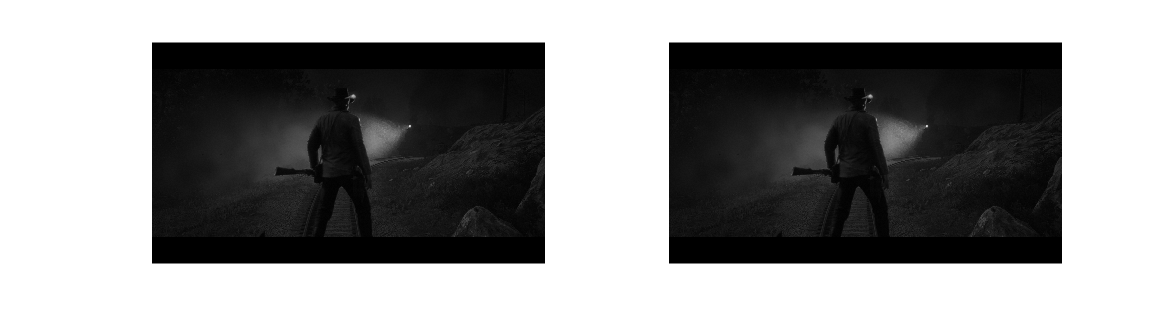

subplot(1, 2, 1);
imshow(orgPicture);
subplot(1, 2, 2);
imshow(codedPicture);

**1-4) **After encoding the image, we use `decoding` function to extract the encoded message. We iterate through pixels and for each pixel we get the LCB, which is our embedded bit, using `getbit` function. Then for each 5 bit which is our encoded character, we find the corresponding character in Mapset and add it to the output message. We stop extracting the bits when we hit `11111` which corresponds to semicolon ";" and shows our message's end.

msg = decoding(codedPicture, Mapset);
disp(msg);

hatef ride;


**1-5)** Since we are encoding the bits inside the Least Significant Bit of each pixel, with even small noises, the value of LCB bit of pixel can change, so the message can be corrupted and we would not be able to decode it.

Functions implementations

function enhancedImage = coding(image, message, Mapset)
    binaryMessage = '';
    for i = 1:length(message)
        index = find(strcmp(Mapset(1,:), message(i)));
        if isempty(index)
            error("Character not found inside mapset.");
        end
        binaryMessage = [binaryMessage, Mapset{2, index}];
    end

    if size(image, 3) == 3
        image = myGrayFunc(image);
    end
    enhancedImage = image;
    binaryImage = dec2bin(image, 8);
    [rows, cols] = size(image);
    if length(binaryMessage) > rows*cols
        error('The message is too long to fit in the image.');
    end

    for i = 1:length(binaryMessage)
        row = ceil(i / cols);
        col = mod(i-1, cols) + 1;
        
        enhancedImage(row, col) = bitset(image(row, col), 1, str2num(binaryMessage(i)));
    end

    enhancedImage = uint8(enhancedImage);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function message = decoding(codedImage, Mapset)
    codedImage = double(codedImage);
    message = '';
    [rows, cols] = size(codedImage);
    message_bin = zeros(rows*cols, 1);
    for i = 1:rows*cols
        row = ceil(i / cols);
        col = mod(i-1, cols) + 1;
        message_bin(i) = bitget(codedImage(row, col), 1);
        if mod(i, 5) == 0
            chars = '';
            str = message_bin(i-4:i);
            for j = 1:5
                chars = [chars, num2str(str(j))];
            end
            index = find(strcmp(Mapset(2,:), chars));
            message = [message, Mapset{1, index}];
            if all(str == 1)
                break;
            end
        end
        
    end
end
